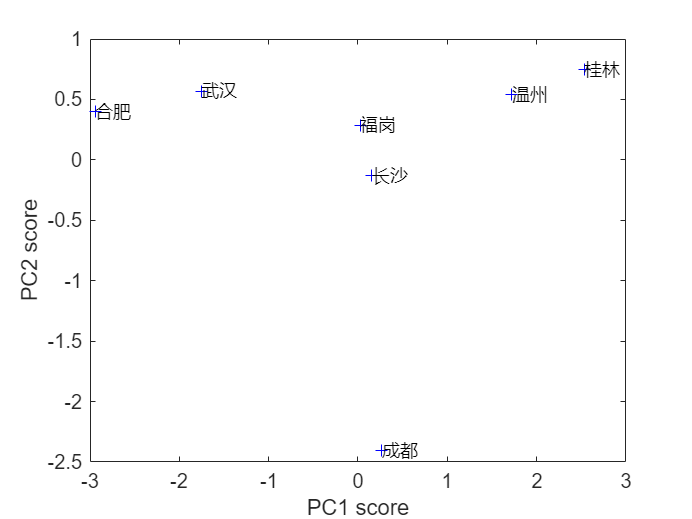

%福冈甜橘引种的主成分分析
clear                                       %清理内存
CN=['合肥';'武汉';'长沙';'桂林';'温州';'成都';'福岗'];
X=[15.7  970   2209  -20.6  1.9
16.3  1260  2085  -17.3  2.8
17.2  1422  1726  -9.5   4.6
18.8  1874  1709  -4.9   8.0
17.9  1698  1848  -4.5  7.5
16.3  976   1239  -4.6   5.6
16.2  1492  2000  -8.2  6.2];
Y=zscore(X);                                %原始变量集体标准化
% [E,score,eigv,T]=princomp(Y);               %调用主成分分析程序
[E,score,eigv,T]=pca(Y);               %调用主成分分析程序
F=score(:,1:2);                             %提取第一、第二主成分的得分
plot(F(:,1),F(:,2),'b+');                   %二维二维主成分散点图
xlabel('PC1 score')                         %横轴标签(第一主成分得分)
ylabel('PC2 score')                         %纵轴标签(第二主成分得分)
text(F(:,1),F(:,2),CN,'FontSize',9);        %静态标注各城市（原为交互式gname，批量运行时无法交互）

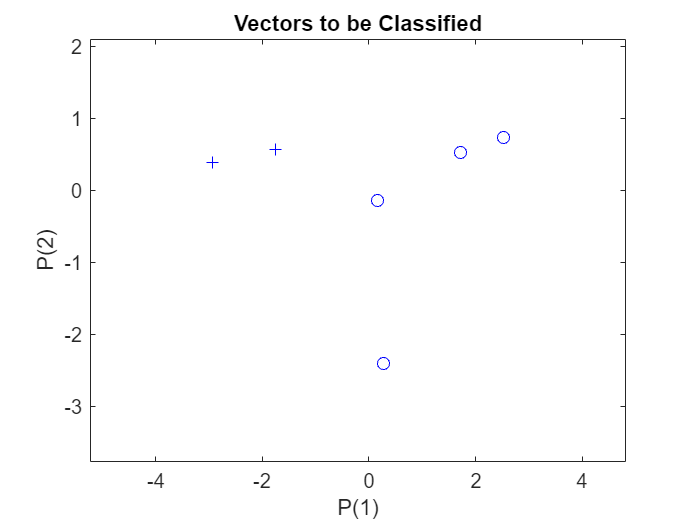

figure                                      %保持主成分得分图
%基于主成分分析建立神经网络模型
P=F(1:length(F)-1,:)';                      %利用主成分得分构建输入信号
Q=F(length(F),:)';                          %基于主成分得分的待判样品信息
T=[1 1 0 0 0 0];                            %基于主成分得分的目标输出
plotpv(P,T);                                %画出中国六城市两大类别的散点图

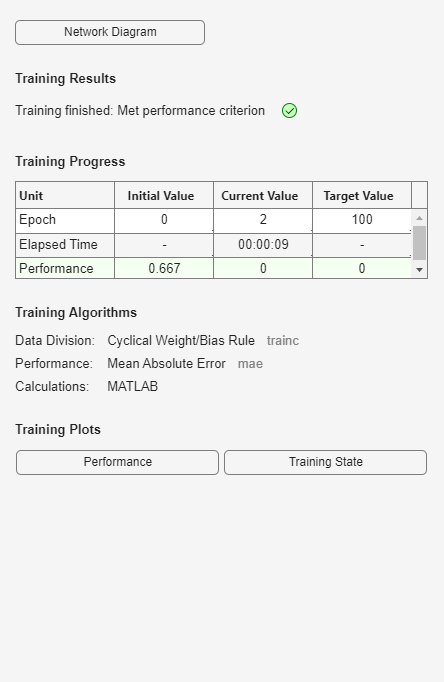

net=newp(minmax(P),1);                      %创建一个感知器网络
net.trainParam.epochs=100;                  %指定最大训练次数
net=train(net,P,T);                         %网络训练

Yp=sim(net,P)                               %训练样品的预报结果

Yp =      1     1     0     0     0     0


Y=sim(net,Q)                                %待判样品的归类结果

Y = 1

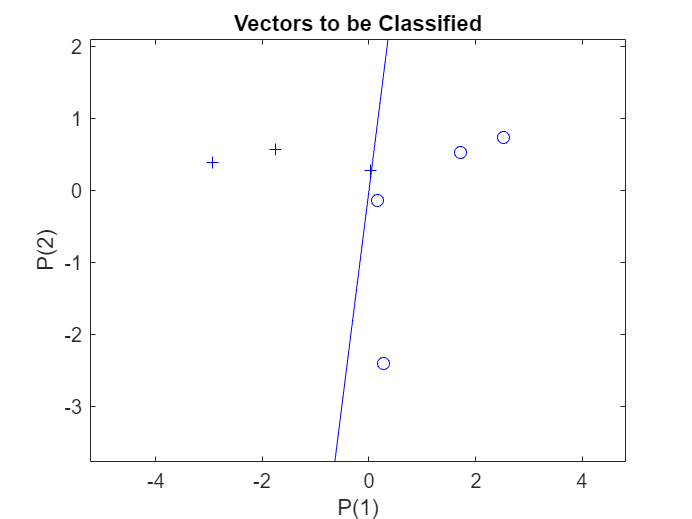

figure                                      %保持网络训练过程图
plotpv([P Q],[T Y]);                        %画出城市二类别散点图
handle=plotpc(net.iw{1,1},net.b{1});        %添加分界线